clc;
clear;
close all;

%% Define the Plant Transfer Function
num = 1;
den = [1 3 2];        % Example system: 1/(s^2+3s+2)
G = tf(num,den);

disp('Plant Transfer Function:')

Plant Transfer Function:


G


G =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.


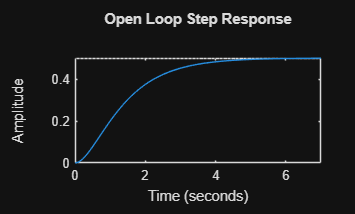


%% Open Loop Analysis
figure;
step(G);
title('Open Loop Step Response');

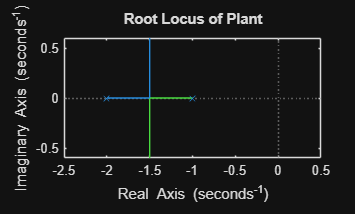


figure;
rlocus(G);
title('Root Locus of Plant');

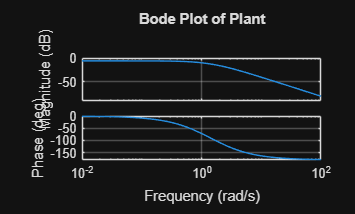


figure;
bode(G);
grid on;
title('Bode Plot of Plant');


%% Lead Compensator Design
z1 = 2;       % zero
p1 = 10;      % pole
K1 = 5;

Gc_lead = K1*tf([1 z1],[1 p1]);

G_lead = series(Gc_lead,G);

disp('Lead Compensated System:')

Lead Compensated System:


G_lead


G_lead =
 
          5 s + 10
  ------------------------
  s^3 + 13 s^2 + 32 s + 20
 
Continuous-time transfer function.


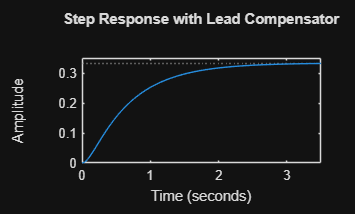


figure;
step(feedback(G_lead,1));
title('Step Response with Lead Compensator');


%% Lag Compensator Design
z2 = 1;
p2 = 0.1;
K2 = 3;

Gc_lag = K2*tf([1 z2],[1 p2]);

G_lag = series(Gc_lag,G);

disp('Lag Compensated System:')

Lag Compensated System:


G_lag


G_lag =
 
            3 s + 3
  ---------------------------
  s^3 + 3.1 s^2 + 2.3 s + 0.2
 
Continuous-time transfer function.


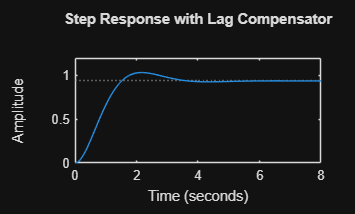


figure;
step(feedback(G_lag,1));
title('Step Response with Lag Compensator');

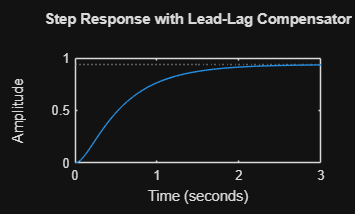


%% Lead-Lag Compensator
Gc_leadlag = series(Gc_lead,Gc_lag);

G_leadlag = series(Gc_leadlag,G);

figure;
step(feedback(G_leadlag,1));
title('Step Response with Lead-Lag Compensator');

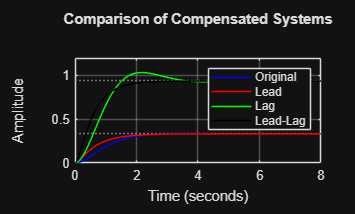


%% Comparison of Responses
figure;
step(feedback(G,1),'b', ...
     feedback(G_lead,1),'r', ...
     feedback(G_lag,1),'g', ...
     feedback(G_leadlag,1),'k');

legend('Original','Lead','Lag','Lead-Lag');
title('Comparison of Compensated Systems');
grid on;